% --- EGS Coursework: Case A (Smart Home) + EV Extension ---
clear; clc; close all;

%% SECTION 1: Data Setup and Parameters
% Load the exact datasets provided
home_data = readtable('caseA_smart_home_30min_summer.csv');
ev_data = readtable('caseA_ev_events.csv'); 

T = height(home_data); % Total number of time steps (1440 for 30 days)
dt = 0.5; % 30-minute resolution means each step is 0.5 hours

% Home Battery Parameters
E_max = 5.0; % Battery holds 5 kWh max
P_ch_max = 2.5; % Max charge speed is 2.5 kW
P_dis_max = 2.5; % Max discharge speed is 2.5 kW
eta_ch = 0.95; % 95% efficient when charging 
eta_dis = 0.95; % 95% efficient when discharging
E_init = 2.5; % Starts 50% full (2.5 kWh)

% Extract exact columns from the summer dataset
P_PV = home_data.pv_kw;
P_L = home_data.base_load_kw;
C_imp = home_data.import_tariff_gbp_per_kwh;
C_exp = home_data.export_price_gbp_per_kwh;
time_series = home_data.timestamp;

%% SECTION 2: Map the EV Events to the Timeline
% This maps the arrival and departure times from the EV dataset to our 30-min steps
num_ev_events = height(ev_data);
ev_arrival_idx = zeros(num_ev_events, 1);
ev_departure_idx = zeros(num_ev_events, 1);
ev_req_kwh = ev_data.required_energy_kwh;
ev_max_kw = ev_data.max_charge_power_kw;

% Find the matching time index for each EV event
for i = 1:num_ev_events
    [~, arr_idx] = min(abs(time_series - ev_data.arrival_time(i)));
    [~, dep_idx] = min(abs(time_series - ev_data.departure_time(i)));
    ev_arrival_idx(i) = arr_idx;
    ev_departure_idx(i) = dep_idx;
end

%% SECTION 3: Policy 1 (Simple Self-Consumption Rule)
P_B_ch_1 = zeros(T,1); P_B_dis_1 = zeros(T,1);
P_G_imp_1 = zeros(T,1); P_G_exp_1 = zeros(T,1);
E_SOC_1 = zeros(T+1,1); E_SOC_1(1) = E_init;
P_EV_1 = zeros(T,1);

% EV charging logic: Charge the car at max speed as soon as it arrives
for i = 1:num_ev_events
    energy_delivered = 0;
    for t = ev_arrival_idx(i) : ev_departure_idx(i)-1
        if energy_delivered < ev_req_kwh(i)
            P_EV_1(t) = min(ev_max_kw(i), (ev_req_kwh(i) - energy_delivered)/dt);
            energy_delivered = energy_delivered + P_EV_1(t)*dt;
        end
    end
end

% House logic: Try to use solar power locally before buying from grid
for t = 1:T
    P_net = P_L(t) + P_EV_1(t) - P_PV(t); % Total power needed right now
    
    if P_net > 0 % We need power (deficit)
        P_B_dis_1(t) = min([P_dis_max, P_net, (E_SOC_1(t) - 0)/(eta_dis * dt)]);
        P_G_imp_1(t) = P_net - P_B_dis_1(t);
    else % We have extra solar power (surplus)
        P_B_ch_1(t) = min([P_ch_max, abs(P_net), (E_max - E_SOC_1(t))/(eta_ch * dt)]);
        P_G_exp_1(t) = abs(P_net) - P_B_ch_1(t);
    end
    % Update the battery level for the next step
    E_SOC_1(t+1) = E_SOC_1(t) + (P_B_ch_1(t)*eta_ch - P_B_dis_1(t)/eta_dis)*dt;
end

cost_policy1 = sum((P_G_imp_1 .* C_imp - P_G_exp_1 .* C_exp) * dt);

%% SECTION 4: Policy 2 (Smart Cost Optimisation)
prob = optimproblem('ObjectiveSense', 'minimize');

% Variables for the computer to decide
P_B_ch = optimvar('P_B_ch', T, 1, 'LowerBound', 0, 'UpperBound', P_ch_max);
P_B_dis = optimvar('P_B_dis', T, 1, 'LowerBound', 0, 'UpperBound', P_dis_max);
P_G_imp = optimvar('P_G_imp', T, 1, 'LowerBound', 0);
P_G_exp = optimvar('P_G_exp', T, 1, 'LowerBound', 0);
E_SOC = optimvar('E_SOC', T+1, 1, 'LowerBound', 0, 'UpperBound', E_max);
P_EV = optimvar('P_EV', T, 1, 'LowerBound', 0);

% Goal: Make the total cost as low as possible over the whole month
prob.Objective = sum((P_G_imp .* C_imp - P_G_exp .* C_exp) * dt);

% Hard rules
prob.Constraints.EnergyBalance = P_PV + P_B_dis + P_G_imp == P_L + P_B_ch + P_G_exp + P_EV;
prob.Constraints.SOC_Update = E_SOC(2:end) == E_SOC(1:end-1) + (P_B_ch * eta_ch - P_B_dis / eta_dis) * dt;
prob.Constraints.InitialSOC = E_SOC(1) == E_init;
prob.Constraints.FinalSOC = E_SOC(end) >= E_init;

% EV Constraints for all charging events
% 1. EV power is 0 when the car is away
is_plugged_in = false(T, 1);
for i = 1:num_ev_events
    is_plugged_in(ev_arrival_idx(i):ev_departure_idx(i)-1) = true;
end
prob.Constraints.EV_OffTime = P_EV(~is_plugged_in) == 0;

% 2. EV cannot exceed its max charging power (usually 7kW or 3.6kW)
% 3. EV must hit its exact energy target before it leaves
for i = 1:num_ev_events
    idx_range = ev_arrival_idx(i) : ev_departure_idx(i)-1;
    % Limit charge speed
    prob.Constraints.(sprintf('EV_MaxPower_%d', i)) = P_EV(idx_range) <= ev_max_kw(i);
    % Guarantee energy requirement is met
    prob.Constraints.(sprintf('EV_Energy_%d', i)) = sum(P_EV(idx_range)) * dt == ev_req_kwh(i);
end

% Solve the puzzle to find the best path
options = optimoptions('linprog','Display','none');
[sol, cost_policy2] = solve(prob, 'Options', options);

%% SECTION 5: Safety Checks (Evidence-Based Verification)
% Check 1: Did energy balance out?
balance_error = max(abs((P_PV + sol.P_B_dis + sol.P_G_imp) - (P_L + sol.P_B_ch + sol.P_G_exp + sol.P_EV)));
assert(balance_error < 1e-5, 'Error: Energy did not balance!');

% Check 2: Did the battery stay within limits?
assert(max(sol.E_SOC) <= E_max + 1e-5, 'Error: Battery overcharged!');
assert(min(sol.E_SOC) >= -1e-5, 'Error: Battery dropped below zero!');

fprintf('All safety checks passed! The math is correct.\n');

All safety checks passed! The math is correct.


fprintf('Policy 1 Total Cost: £%.2f\n', cost_policy1);

Policy 1 Total Cost: £164.50


fprintf('Policy 2 Total Cost: £%.2f\n', cost_policy2);

Policy 2 Total Cost: £85.25


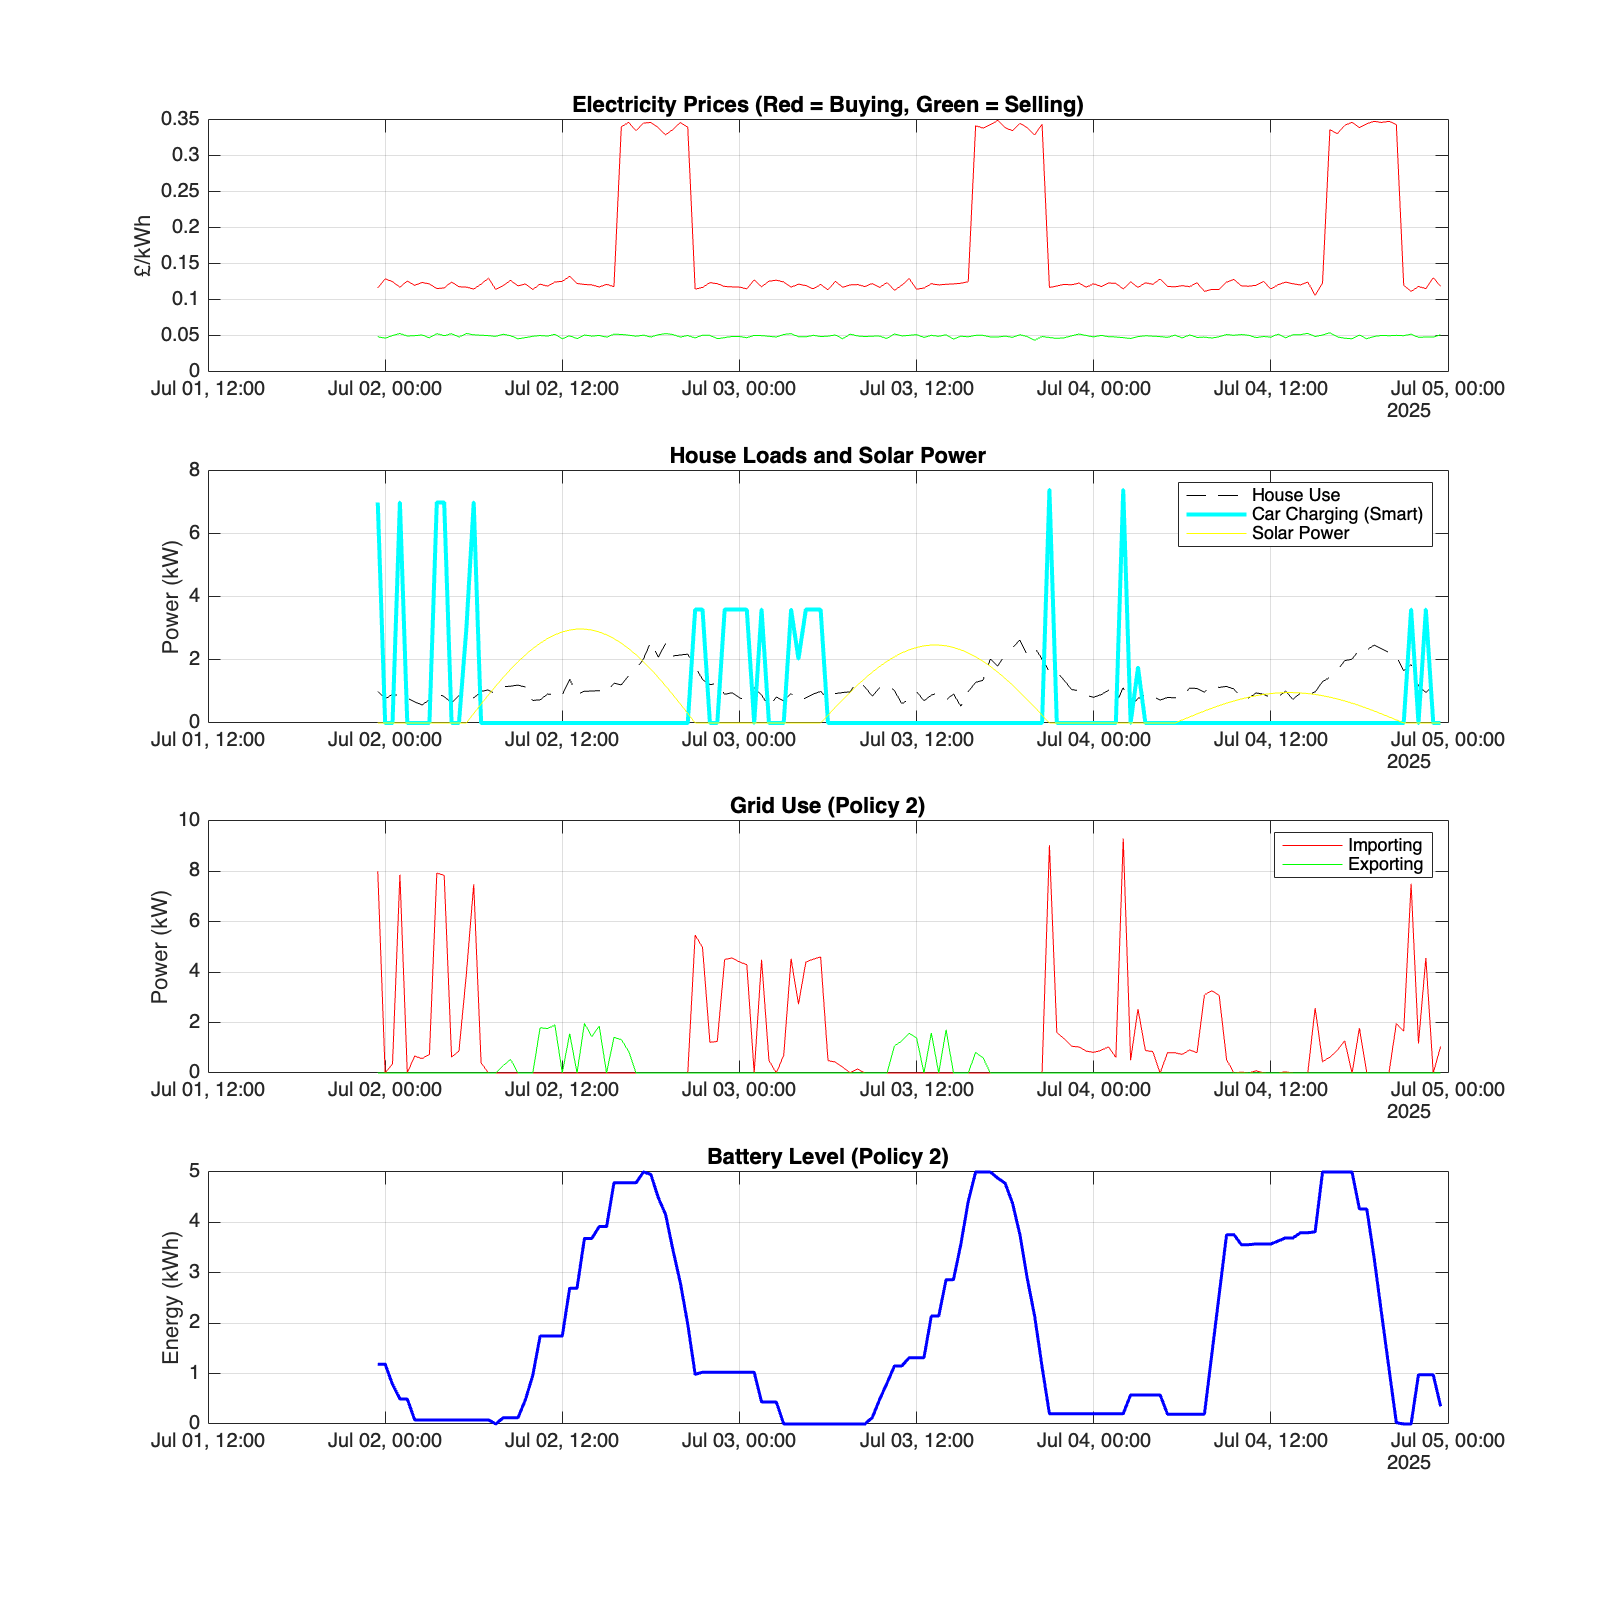


%% SECTION 6: Draw the Graphs (Engineering Insights)
% We will plot just a 3-day window (e.g., from day 2 to day 4) so you can actually see the lines clearly
plot_start = 48;  % Start of day 2
plot_end = 192;   % End of day 4
time_window = plot_start:plot_end;

figure('Position', [100, 100, 800, 800]);

subplot(4,1,1);
plot(time_series(time_window), C_imp(time_window), 'r'); hold on; 
plot(time_series(time_window), C_exp(time_window), 'g');
title('Electricity Prices (Red = Buying, Green = Selling)'); ylabel('£/kWh'); grid on;

subplot(4,1,2);
plot(time_series(time_window), P_L(time_window), 'k--'); hold on; 
plot(time_series(time_window), sol.P_EV(time_window), 'c', 'LineWidth', 2); 
plot(time_series(time_window), P_PV(time_window), 'y');
title('House Loads and Solar Power'); ylabel('Power (kW)'); 
legend('House Use', 'Car Charging (Smart)', 'Solar Power'); grid on;

subplot(4,1,3);
plot(time_series(time_window), sol.P_G_imp(time_window), 'r'); hold on; 
plot(time_series(time_window), sol.P_G_exp(time_window), 'g');
title('Grid Use (Policy 2)'); ylabel('Power (kW)'); legend('Importing', 'Exporting'); grid on;

subplot(4,1,4);
plot(time_series(time_window), sol.E_SOC(time_window), 'b', 'LineWidth', 1.5);
title('Battery Level (Policy 2)'); ylabel('Energy (kWh)'); grid on;

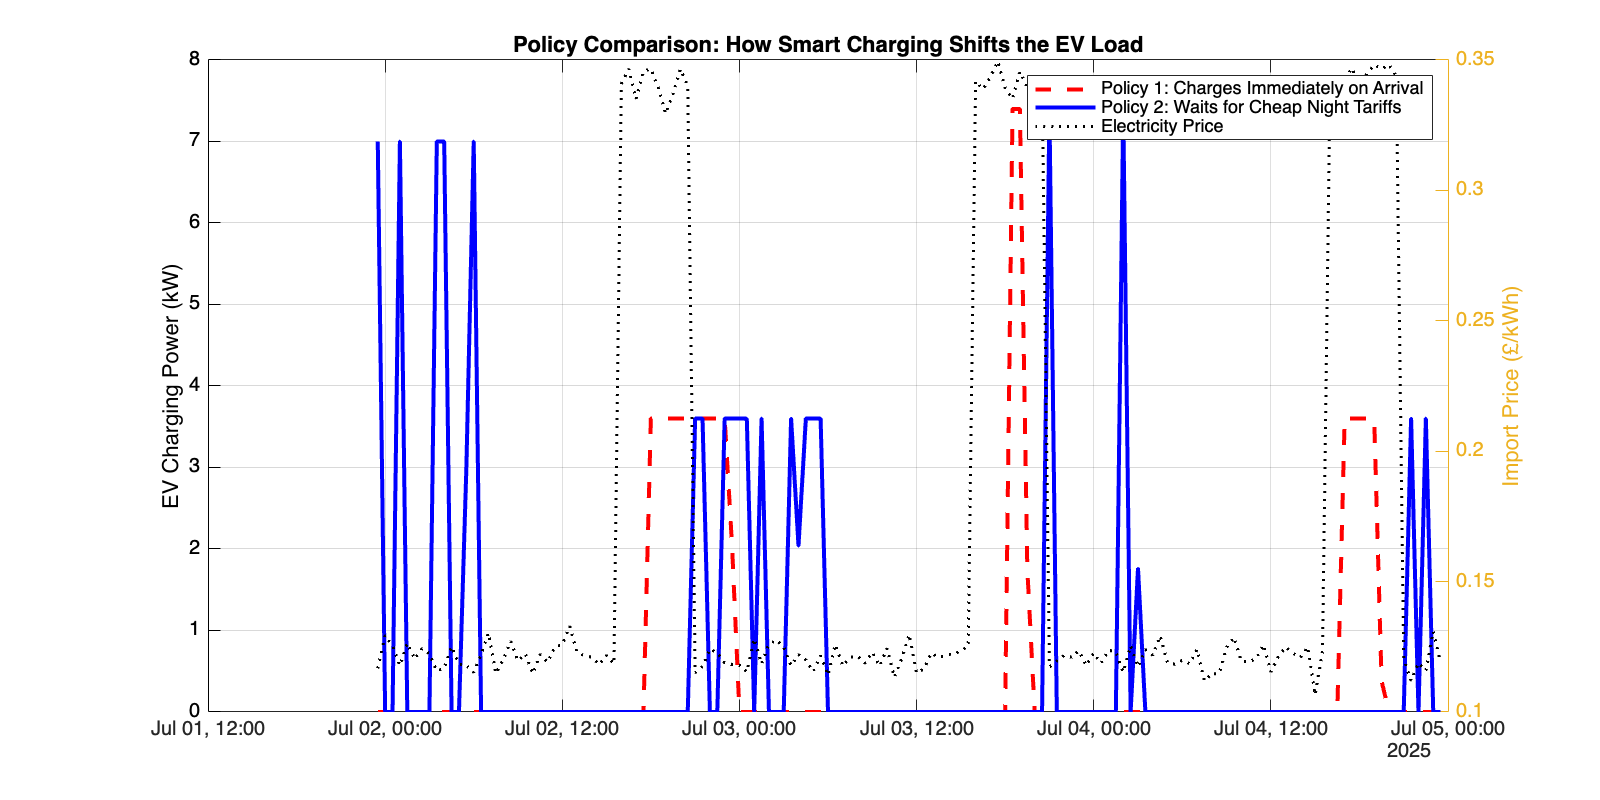


%% SECTION 7: Extra Graphs for Policy Comparison & Breakdowns

% --- Graph A: EV Charging Comparison (Policy 1 vs Policy 2) ---
figure('Position', [150, 150, 800, 400]);
% Plot Policy 1 EV charging (Red Dashed)
plot(time_series(time_window), P_EV_1(time_window), 'r--', 'LineWidth', 2); hold on;
% Plot Policy 2 EV charging (Blue Solid)
plot(time_series(time_window), sol.P_EV(time_window), 'b', 'LineWidth', 2);
% Plot the price in the background on a different axis
yyaxis right; 
plot(time_series(time_window), C_imp(time_window), 'k:', 'LineWidth', 1.5);
ylabel('Import Price (£/kWh)');
yyaxis left; 

title('Policy Comparison: How Smart Charging Shifts the EV Load');
ylabel('EV Charging Power (kW)');
legend('Policy 1: Charges Immediately on Arrival', 'Policy 2: Waits for Cheap Night Tariffs', 'Electricity Price');
grid on;

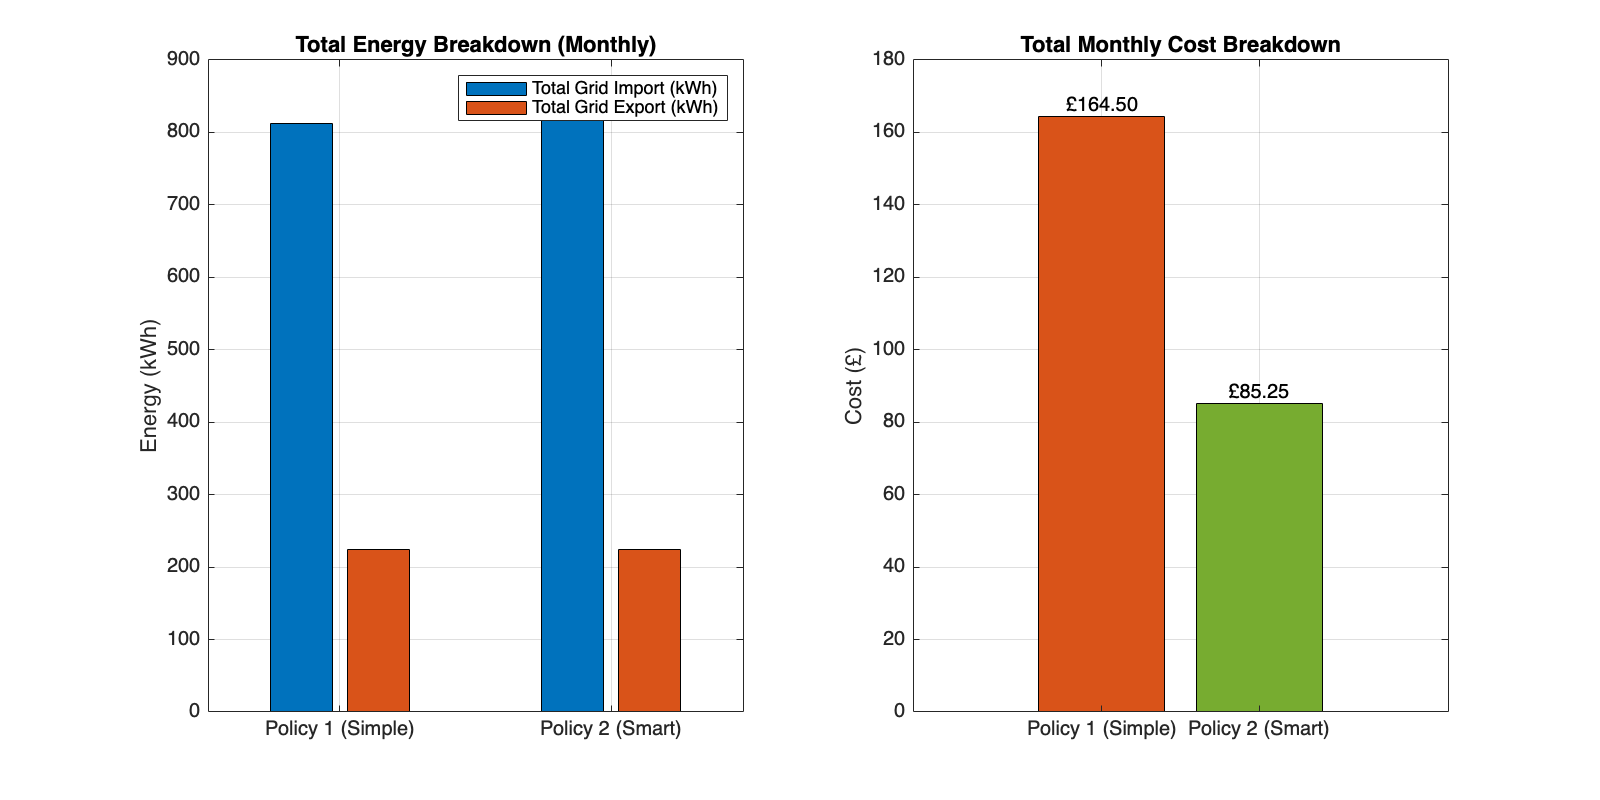


% --- Graph B: Energy and Cost Breakdown Bar Charts ---
% Calculate the totals for the whole month
Total_Import_1 = sum(P_G_imp_1) * dt; Total_Export_1 = sum(P_G_exp_1) * dt;
Total_Import_2 = sum(sol.P_G_imp) * dt; Total_Export_2 = sum(sol.P_G_exp) * dt;

figure('Position', [200, 200, 800, 400]);

% Subplot 1: Energy Imports vs Exports
subplot(1,2,1);
energy_data = [Total_Import_1, Total_Export_1; Total_Import_2, Total_Export_2];
bar(energy_data);
set(gca, 'XTickLabel', {'Policy 1 (Simple)', 'Policy 2 (Smart)'});
legend('Total Grid Import (kWh)', 'Total Grid Export (kWh)');
title('Total Energy Breakdown (Monthly)');
ylabel('Energy (kWh)');
grid on;

% Subplot 2: Total Cost Comparison
subplot(1,2,2);
cost_data = [cost_policy1; cost_policy2];
b = bar(cost_data);
b.FaceColor = 'flat';
b.CData(1,:) = [0.8500, 0.3250, 0.0980]; % Red for Policy 1
b.CData(2,:) = [0.4660, 0.6740, 0.1880]; % Green for Policy 2
set(gca, 'XTickLabel', {'Policy 1 (Simple)', 'Policy 2 (Smart)'});
title('Total Monthly Cost Breakdown');
ylabel('Cost (£)');
grid on;

% Add text on top of the bars to show the exact price
text(1, cost_policy1, sprintf('£%.2f', cost_policy1), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
text(2, cost_policy2, sprintf('£%.2f', cost_policy2), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');